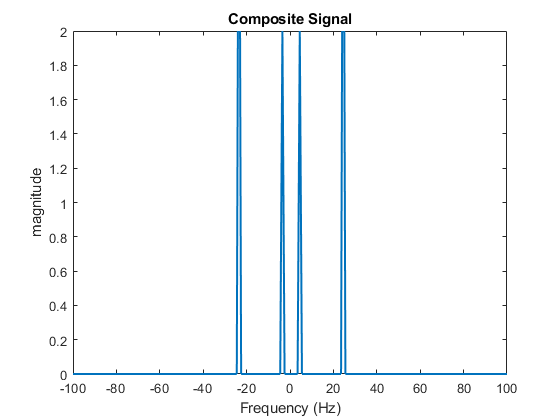

%Task1
%AB-CDEFG-H
%20-42406-1
%AMP1=A+B=2;AMP2 = E+F=4
%FREQ1= BC=04;FREQ2=DE=24
fs=1000;
a1=2;
a2=4;
f1=04;
f2=24;
t=0:1/fs:1-1/fs;
x1=a1*sin(2*3.1416*f1*t);
x2=a2*sin(2*3.1416*f2*t+30*(3.1416/180));
x=a1*sin(2*3.1416*f1*t)+a2*sin(2*3.1416*f2*t+30);
fx=fft(x);
fx=fftshift(fx)/(fs/2);
f = fs/2*linspace(-1,1,fs);
figure;
plot(f, abs(fx),'LineWidth',1.5);
title('Composite Signal');
axis([-100 100 0 2])
xlabel('Frequency (Hz)');
ylabel('magnitude');

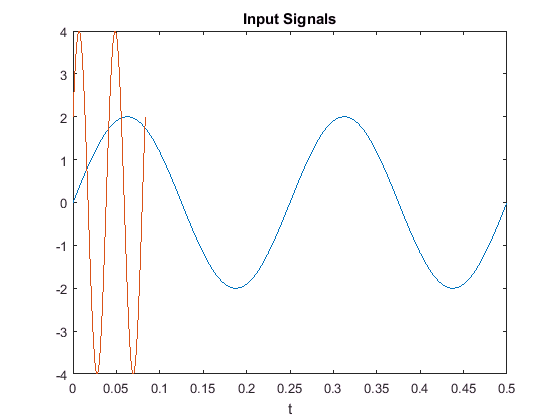

%Task2
a1 = 2;
a2 = 4;
f1 = 04;
f2 = 24;
P1 = 0;
P2 = 30*pi/180;
T1 = 1/f1;
T2 = 1/f2;
t1 = linspace(0,2*T1,1000);
t2 = linspace(0,2*T2,1000);
x1 = a1*sin(2*pi*f1*t1+P1);
x2 = a2*sin(2*pi*f2*t2+P2);
plot(t1,x1);
hold on
plot(t2,x2);
xlabel('t');
title('Input Signals');

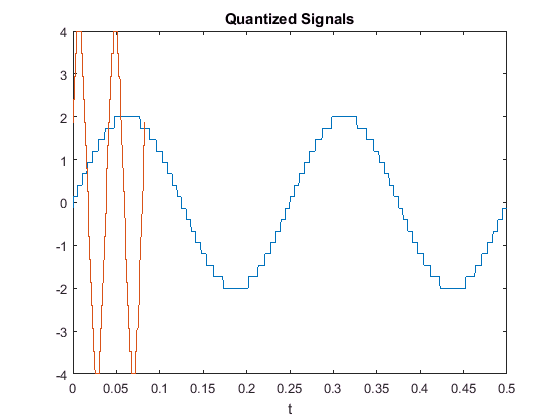

quatization_levels1 = linspace(-a1,a1,16);
quatization_levels2 = linspace(-a2,a2,16);
quatised_x1 = zeros(1,length(x1));
quatised_x2 = zeros(1,length(x2));
for i = 1:length(x1)
[~,index] = min(abs(quatization_levels1-x1(i)));
quatised_x1(i) = quatization_levels1(index);
end
for i = 1:length(x2)
[~,index] = min(abs(quatization_levels2-x2(i)));
quatised_x2(i) = quatization_levels2(index);
end
figure;
plot(t1,quatised_x1);
hold on
plot(t2,quatised_x2);
xlabel('t');
title('Quantized Signals');

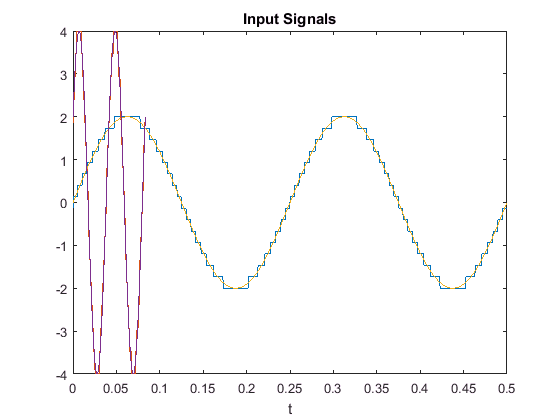

%Task3
a1 = 2; %amp1
a2 = 4; %amp2
f1 = 04; %freq1
f2 = 24; %freq2
P1 = 0;
P2 = 30*pi/180;
T1 = 1/f1;
T2 = 1/f2;
t1 = linspace(0,2*T1,1000);
t2 = linspace(0,2*T2,1000);
x1 = a1*sin(2*pi*f1*t1+P1);
x2 = a2*sin(2*pi*f2*t2+P2);
plot(t1,x1);
hold on
plot(t2,x2);
xlabel('t');
title('Input Signals');

noise_amp = 0.2;
x1_noisy = x1 + noise_amp*randn(1,length(x1));
x2_noisy = x2 + noise_amp*randn(1,length(x2));
signal_power = (sum(x1.^2)+sum(x2.^2))/1000;
noise_power = noise_amp*95;
SNR = signal_power/noise_power;
SNRdB = 10*log10(SNR);
fprintf('SNR = %f, and in dB = %f\n',SNR,SNRdB);

SNR = 0.526000, and in dB = -2.790143


SNR = 4.259961, dB = 6.294056

SNR = 4.2600

dB = 6.2941

capacity = 95*log2(1+SNR)

capacity = 227.5299

%Task4
fs=8000;
f=400;
t=0:1/fs:1-1/fs;
AMP1=2;
powfund=AMP1^2/2;
AMP2=4;
powharm = AMP2^2/2;
S1=0.25;
S2=0.5;
FREQ1=04; FREQ2=24;
x1 = AMP1*cos(2*pi*FREQ1*t) + AMP2*sin(2*pi*FREQ2*t) + S1*randn(size(t));
THD1 = thd(x1)

THD1 = -41.2954

x2 = AMP1*cos(2*pi*FREQ1*t) + AMP2*sin(2*pi*FREQ2*t) +S2*randn(size(t));
THD2 = thd(x2)

THD2 = -37.9405

BW1=obw(x1,fs)

BW1 = 689.5975

Capacity1=BW1*log2(1+THD1)

Capacity1 = 3.6773e+03 + 3.1255e+03i

x2 = AMP1*cos(2*pi*FREQ1*t) + AMP2*sin(2*pi*FREQ2*t) +S2*randn(size(t));
THD2 = thd(x2)

THD2 = -40.5155

BW2=obw(x2,fs)

BW2 = 3.1691e+03

Capacity2=BW2*log2(1+THD2)

Capacity2 = 1.6810e+04 + 1.4364e+04i